#### Maciej Górnik

#### gr 1b, 402325

#### EAIiIB, AiR

# **Układ regulacji dwupołożeniowej - część 2**

## **Cel ćwiczenia**

Celem ćwiczenia było zapoznanie się z działaniem i właściwościami układu regulacji II położeniowej

(przekaźnikowej), która jest najprostszym układem regulacji stosowanym w praktyce, oraz zapoznanie się

z środowiskiem Matlab SIMULINK pozwalającym na modelowanie systemów dynamicznych z użyciem

schematów blokowych.

## Przebieg ćwiczenia

W Simulinku stworzono 3 zamknięte układy regulacji złozone z liniowego obiektu o transmintacjach:

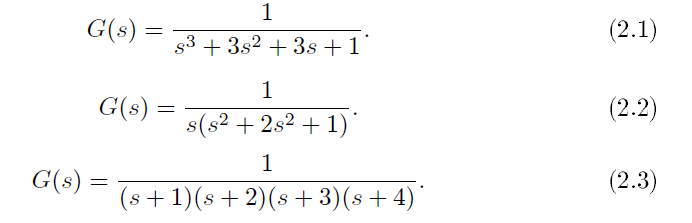

### Modele obiektów w simulinku:

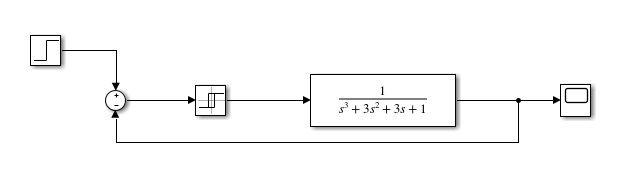

Rys. 1. Obiekt o transmitancji (2.1)

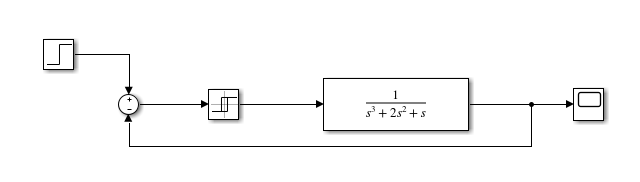

Rys.2. Obiekt o transmitancji (2.2)

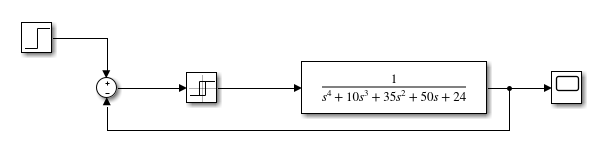

Rys. 3. Obiekt o transmitancji (2.3)

### **Wyznaczanie wartości wzmocnienia krytycznego.**

## Model 1

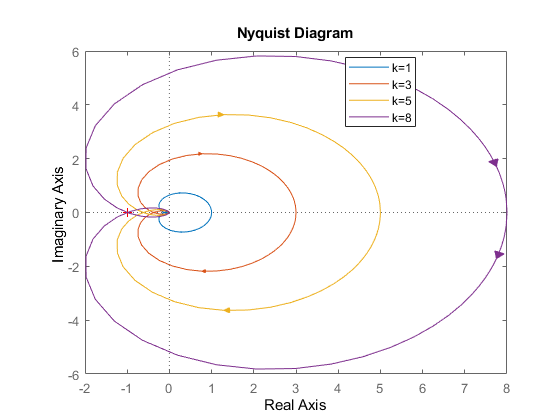

A = 2;
clear;
i = 0;
figure;
for k = [1 3 5 8]
    i = i + 1;
    licz = [k];
    mian = [1 3 3 1];
    l(i) = append("k=", string(k));
    nyquist(licz, mian)
    legend(l,'Location',"best")
    hold on
end

## Model 2

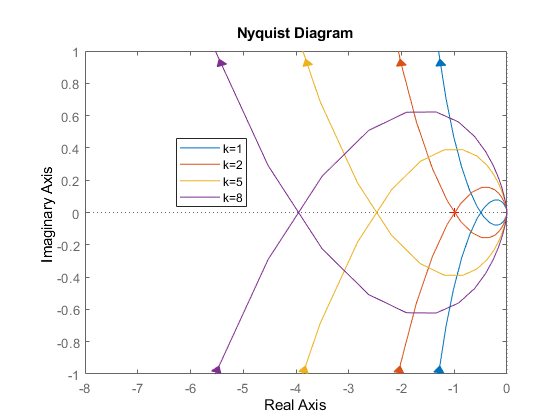

clear;
i = 0;
figure;
for k = [1 2 5 8]
    i = i + 1;
    licz = [k];
    mian = [1 2 1 0];
    l(i) = append("k=", string(k));
    nyquist(licz, mian)
    legend(l,'Location',"best")
    axis([-8 0 -1 1])
    hold on
end

## Model 3

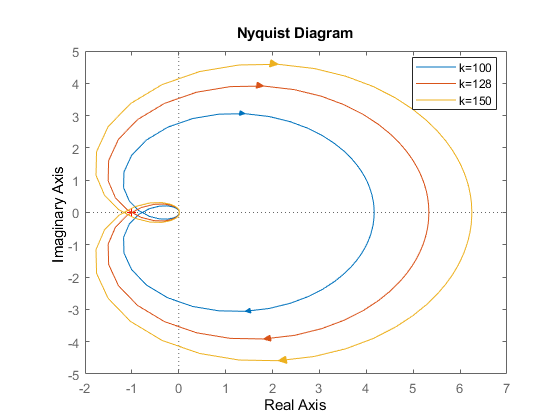

clear;
i = 0;
figure;
for k = [100 128 150]
    i = i + 1;
    licz = [k];
    mian = [1 10 35 50 24];
    l(i) = append("k=", string(k));
    nyquist(licz, mian)
    legend(l,'Location',"best")
    hold on
end

Z powyzyszych wykresów można odczytać, że wzmocnienia krytyczne dla badanych obiektów to są równe kolejno k = 8, k = 2, k = 128.

### Charakterystyki Nyquista z wykresem krytycznym

Ponizsze wykresy przedstawiają charakterystyki Nyquista z wykresem  krytycznym dla róznych wartości ym i h.

## Model 1

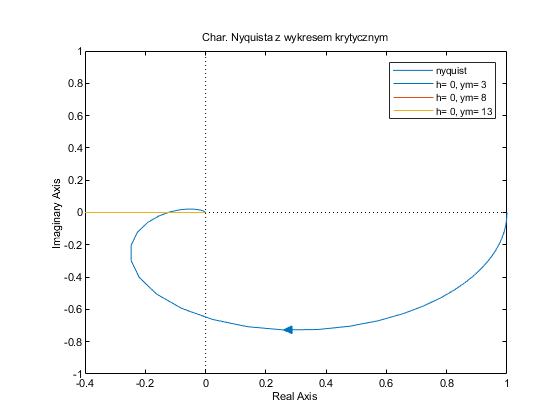

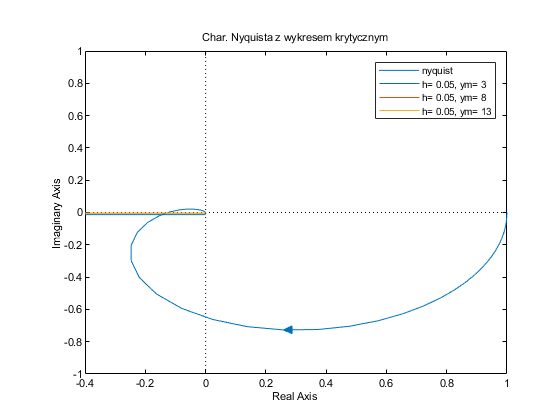

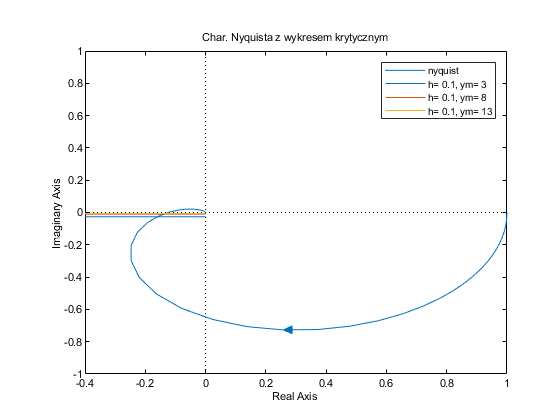

ym = 2;
licz = [1];
mian = [1 3 3 1];
figure;
for h = [0 0.05 0.1]
    figure;
    xlabel('czas[s]');  
    ylabel('y(t)');
    N = nyquistoptions;
    N.ShowFullContour = 'off';
    nyquist = tf(licz, mian);
    hold on;
    p1 = nyquistplot(nyquist, N);
    for ym = [3 8 13]
        tt = linspace(-1,0,50);
        x = ones(1, 50);
        c = ((-pi*h)/(4*ym)) * x;
        l = append("h= ", string(h),", ym= ", string(ym));
        plot(tt,c,'DisplayName',l);
        title('Char. Nyquista z wykresem krytycznym');
        axis([-0.4 1 -1 1])
    end
    legend;
end

## Model 2

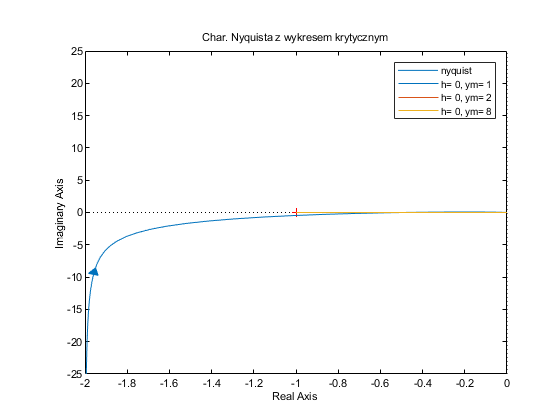

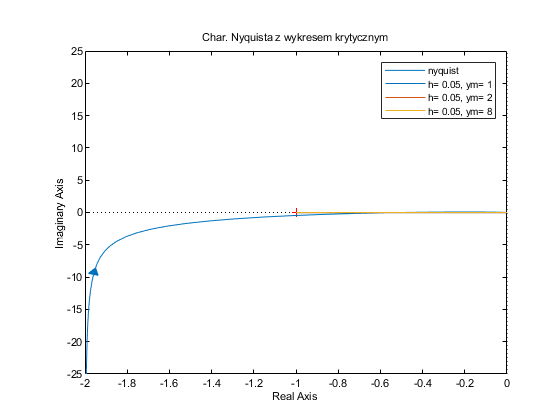

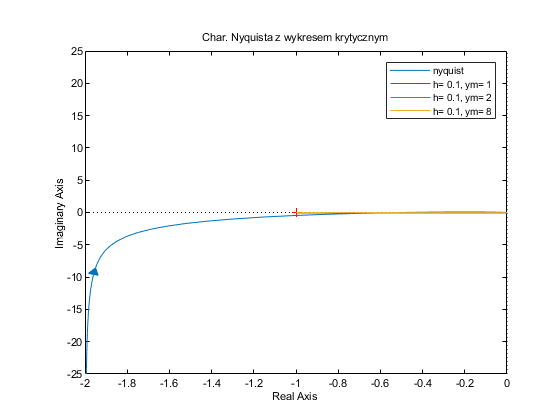

clear;
ym = 2;
licz = [1];
mian = [1 2 1 0];
figure;
for h = [0 0.05 0.1]
    figure;
    xlabel('czas[s]');  
    ylabel('y(t)');
    N = nyquistoptions;
    N.ShowFullContour = 'off';
    nyquist = tf(licz, mian);
    hold on;
    p1 = nyquistplot(nyquist, N);
    for ym = [1 2 8]

        tt = linspace(-1,0,50);
        x = ones(1, 50);
        c = ((-pi*h)/(4*ym)) * x;
        l = append("h= ", string(h),", ym= ", string(ym));
        plot(tt,c,'DisplayName',l);
        title('Char. Nyquista z wykresem krytycznym');
    end
    legend;
end

## Model 3

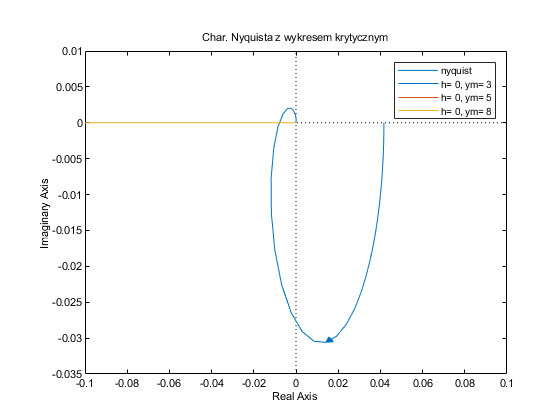

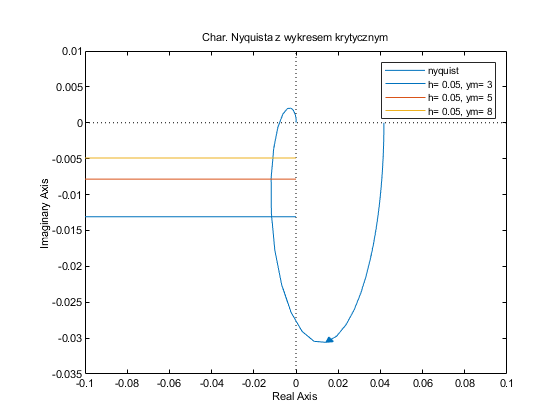

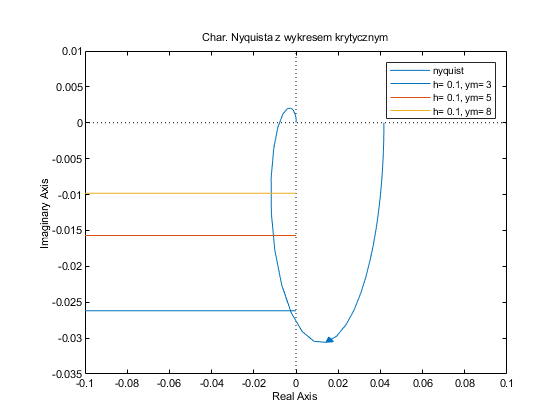

clear;
ym = 2;
licz = [1];
mian = [1 10 35 50 24];
figure;
for h = [0 0.05 0.1]
    figure;
    xlabel('czas[s]');  
    ylabel('y(t)');
    N = nyquistoptions;
    N.ShowFullContour = 'off';
    nyquist = tf(licz, mian);
    hold on;
    p1 = nyquistplot(nyquist, N);
    for ym = [3 5 8]
        tt = linspace(-1,0,50);
        x = ones(1, 50);
        c = ((-pi*h)/(4*ym)) * x;
        l = append("h= ", string(h),", ym= ", string(ym));
        plot(tt,c,'DisplayName',l);
        title('Char. Nyquista z wykresem krytycznym');
        axis([-0.1 0.1 -0.035 0.01])
    end
    legend;
end

### Wyniki symulacji układów w Simuliku

Dla różnych wartości ym i histerezy zbadano przebiegi wyjścia układu dla badanych obiektów

## Model 1

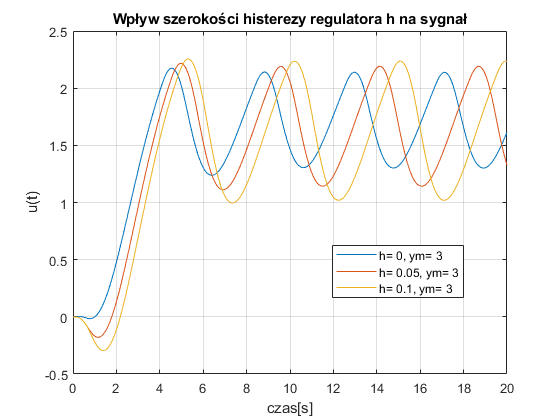

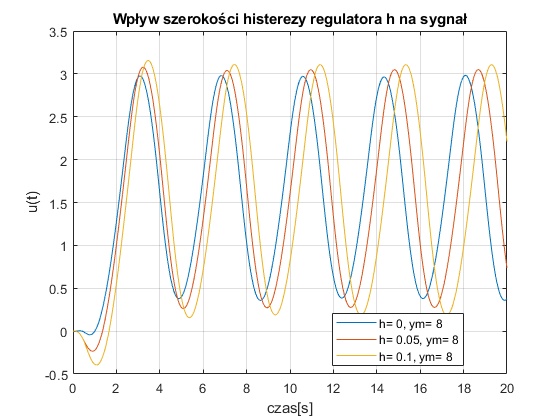

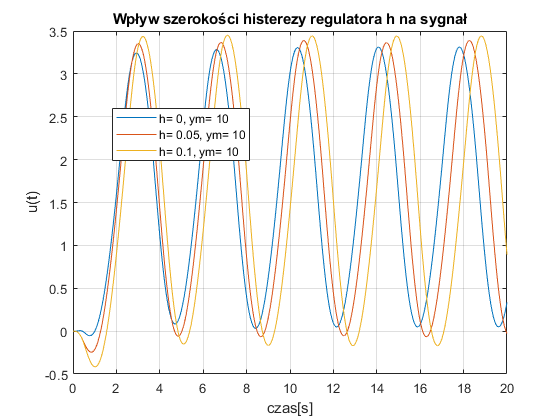

A = 2;
i = 0;
for ym = [3 8 10]
    figure;
    for h=[0 0.05 0.1]
        i = i + 1;
        out = sim('Lab6_1');
        u = out.u;
        l = append("h= ", string(h),", ym= ", string(ym));
        plot(u.time,u.signals.values,'DisplayName',l)
        grid
        xlabel('czas[s]')
        ylabel('u(t)')
        legend("Location","best");
        hold on
    end
    title("Wpływ szerokości histerezy regulatora h na sygnał")
end

## Model 2

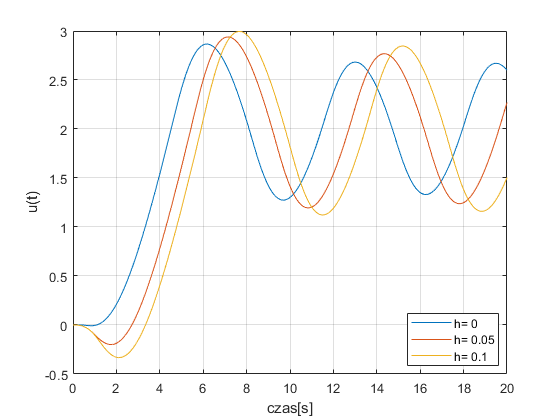

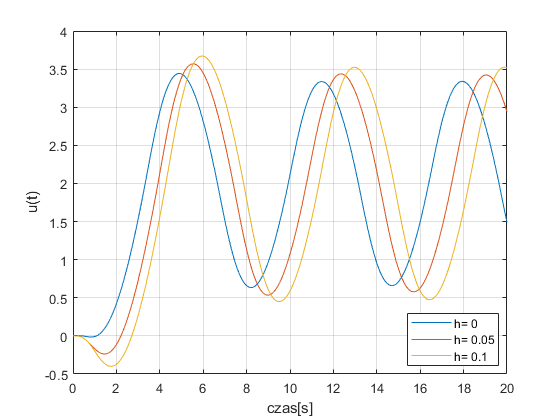

A = 2;
i = 0;
for ym = [1 2 3]
    figure;
    for h=[0 0.05 0.1]
        i = i + 1;
        out = sim('Lab6_1_2');
        u = out.u;
        l = append("h= ", string(h));
        plot(u.time,u.signals.values,'DisplayName',l)
        grid
        xlabel('czas[s]')
        ylabel('u(t)')
        legend("Location","best");
        hold on
    end
end

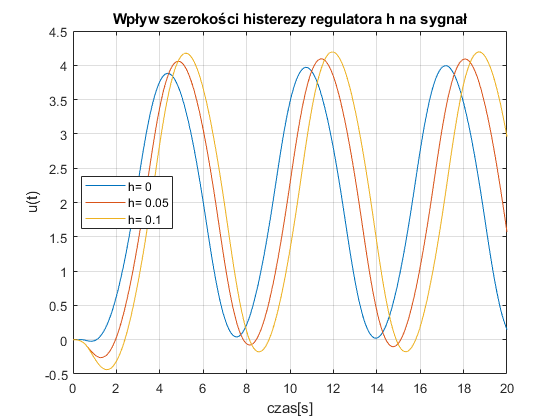

title("Wpływ szerokości histerezy regulatora h na sygnał")

## Model 3

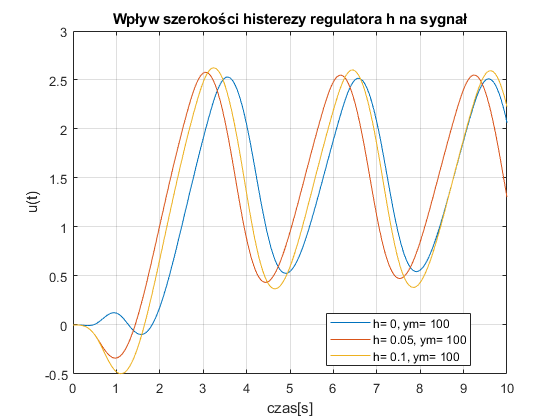

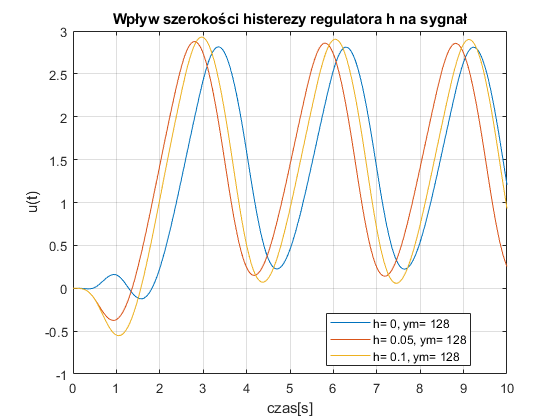

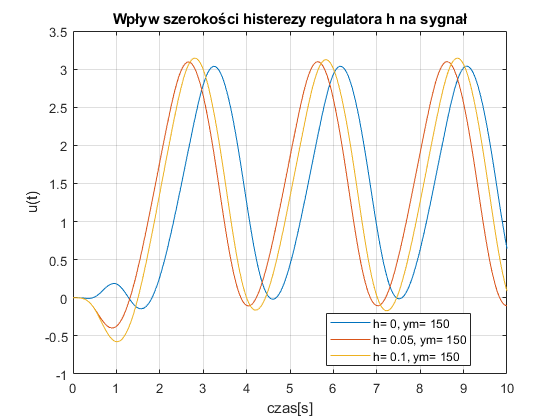

A = 2;
i = 0;
for ym = [100 128 150]
    figure;
    for h=[0 0.05 0.1]
        i = i + 1;
        out = sim('Lab6_1_3');
        u = out.u;
        l = append("h= ", string(h),", ym= ", string(ym));
        plot(u.time,u.signals.values,'DisplayName',l)
        grid
        xlabel('czas[s]')
        ylabel('u(t)')
        legend("Location","best");
        hold on
    end
    title("Wpływ szerokości histerezy regulatora h na sygnał")
end

## **Wnioski**

Podczas badania nauczyliśmy sie wyznaczać, wartości wzmocnienia krytycznego dla róznych wartości transmitancji. Rysowaliśmy również wykresy krytyczne dla badanych układów. Zauwazyliśmy że dla histerezy równej zero wartości wykresu krytycznego są równe zero. Badalismy wpływ zmiany histerezy* h*  oraz wartości amplitudy przekaźnika *ym *wpływa na sygnał wyjsciowy sygnału. Można zauważyć, że wzrost wartości histerezy powoduje delikatne zwiekszenie amplitudy oscylacji sygnału. Wzrost wartości ym powoduje wzrost amplitudy oscylacji sygnałów.